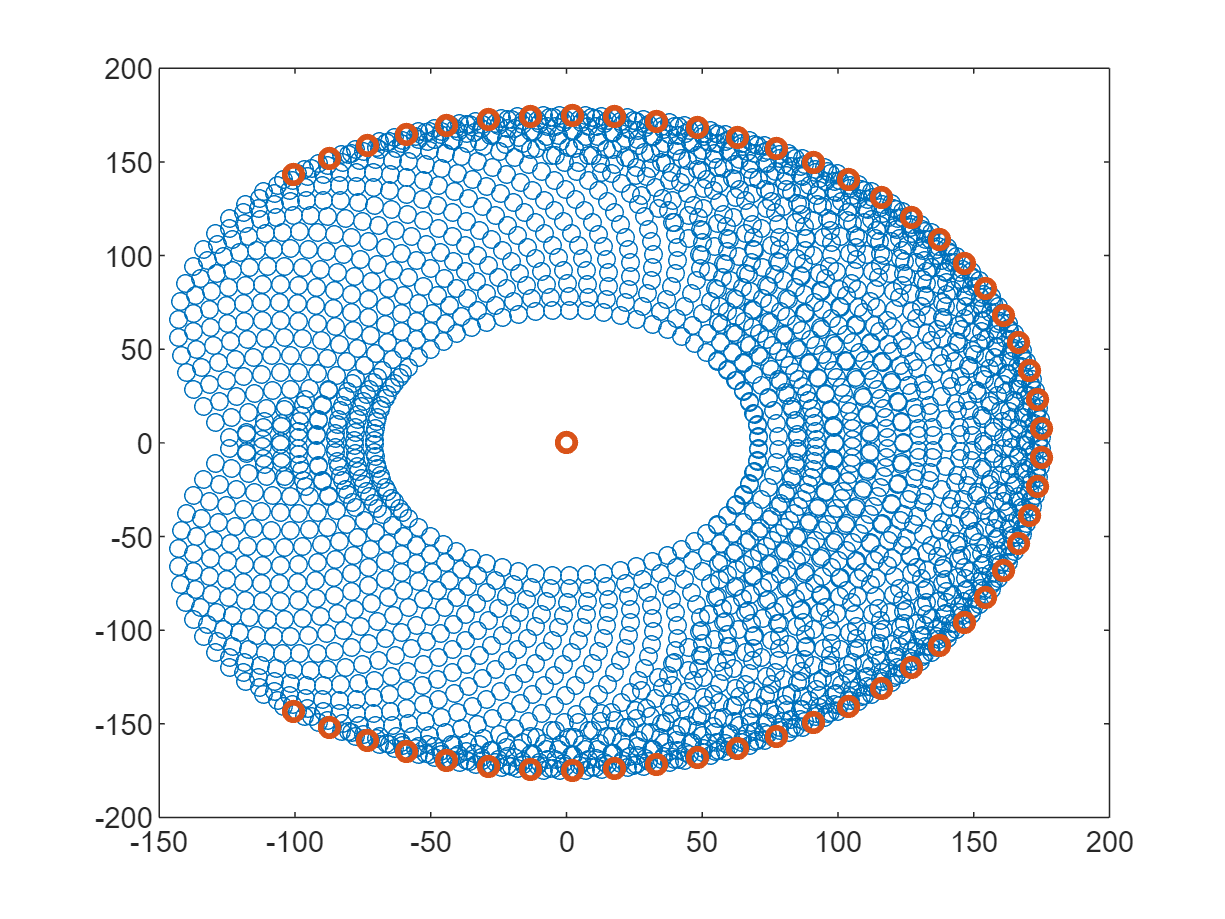

clc
clear

L1 = 75;
L2 = 100;

n = 50;

theta1 =linspace(-125,125,n);
theta2 =linspace(-135,135,n);

Px = zeros(1,n*n);
Py = zeros(1,n*n);

for i = 1 : n
    for j = 1 : n

        x = L1*cosd(theta1(i)) + L2*cosd(theta1(i) + theta2(j));
        y = L1*sind(theta1(i)) + L2*sind(theta1(i) + theta2(j));

        m = j + (i - 1)*n;

        Px(m) = x;
        Py(m) = y;

    end
end

plot(Px,Py,'o')
Pxx = zeros(1,n);
Pyy = zeros(1,n);

for i = 1 : n

        Pxx(i,1) = L1*cosd(theta1(i)) + L2*cosd(theta1(i));
        Pyy(i,1) = L1*sind(theta1(i)) + L2*sind(theta1(i));

end

hold on
plot(Pxx,Pyy,'o','LineWidth',2)